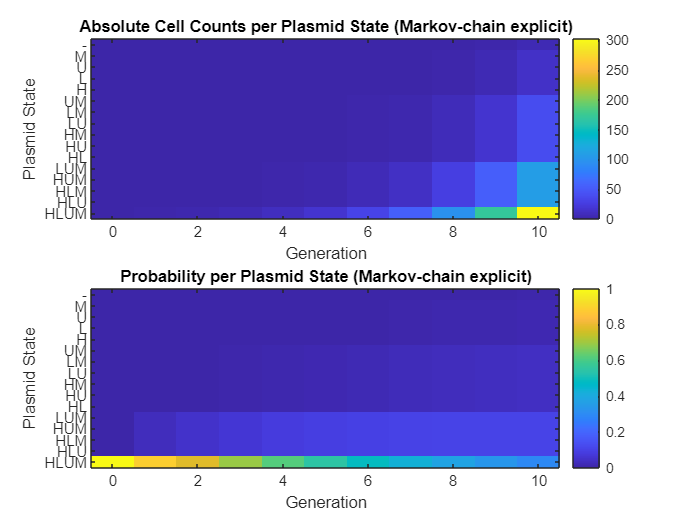

% Parameters
p_s = 0.03;
num_generations = 10;

% Define plasmid states explicitly ordered from fully auxotroph to fully prototroph
plasmid_labels = {'-', 'M', 'U', 'L', 'H', 'UM', 'LM', 'LU', 'HM', 'HU', 'HL', 'LUM', 'HUM', 'HLM', 'HLU', 'HLUM'};
states = [0 0 0 0;
          0 0 0 1;
          0 0 1 0;
          0 1 0 0;
          1 0 0 0;
          0 0 1 1;
          0 1 0 1;
          0 1 1 0;
          1 0 0 1;
          1 0 1 0;
          1 1 0 0;
          0 1 1 1;
          1 0 1 1;
          1 1 0 1;
          1 1 1 0;
          1 1 1 1];

% Transition Matrix T
T = zeros(16,16);
for i = 1:16
    for j = 1:16
        prob = 1;
        for plasmid = 1:4
            if states(i,plasmid) == 1
                prob = prob * ((1-p_s)^(states(j,plasmid)) * p_s^(1-states(j,plasmid)));
            elseif states(j,plasmid) == 1
                prob = 0; % cannot regain plasmid
                break;
            end
        end
        T(i,j) = prob;
    end
end

% Initialize absolute cell counts
cell_counts = zeros(num_generations+1,16);
cell_counts(1,16) = 1; % Start with single HLUM cell

% Evolve cell counts explicitly through generations
for gen = 1:num_generations
    for parent = 1:16
        cell_counts(gen+1,:) = cell_counts(gen+1,:) + cell_counts(gen,parent)*2*T(parent,:);
    end
end

% Calculate probabilities
probabilities = cell_counts ./ sum(cell_counts,2);

% Plotting absolute cell counts
figure;
subplot(2,1,1);
imagesc(0:num_generations,1:16,cell_counts');
colorbar;
xlabel('Generation');
ylabel('Plasmid State');
title('Absolute Cell Counts per Plasmid State (Markov-chain explicit)');
set(gca,'YTick',1:16,'YTickLabel',plasmid_labels);

% Plotting probabilities
subplot(2,1,2);
imagesc(0:num_generations,1:16,probabilities');
colorbar;
xlabel('Generation');
ylabel('Plasmid State');
title('Probability per Plasmid State (Markov-chain explicit)');
set(gca,'YTick',1:16,'YTickLabel',plasmid_labels);


% Verify total cell counts
disp('Total cells per generation (should be 2^n):');

Total cells per generation (should be 2^n):


disp(sum(cell_counts,2)');

   1.0e+03 *

    0.0010    0.0020    0.0040    0.0080    0.0160    0.0320    0.0640    0.1280    0.2560    0.5120    1.0240

